%lab 7 matching / distance transform

clc
clear all
close all

## Problem 1 - templete matching

Please check the documentation of normxcorr2(), there is an example

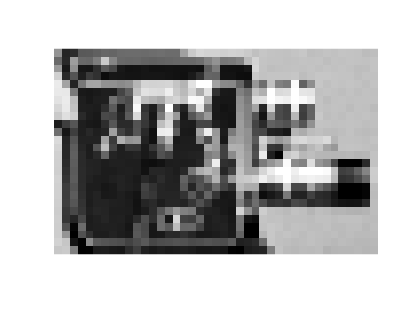

I = imread('cameraman.tif');
% imshow(I);
t = I(60:85,130:170 ); % this is your template image
t_ill = imadjust(t);
imshow(t_ill);

I_ill = imadjust(I);
t_rot = imrotate(t, 90)

t_rot = 41×26 uint8 matrix
   173   177   177   175   177   174   175   170   174   174   172   176   173   176   176   185   184   172   170   172   172   170   172   170   168   166
   171   175   173   176   173   175   175   174   176   173   170   173   174   166    48   124    99    18    18    47   164   171   168   169   167   165
   176   176   172   173   176   173   175   175   174   175   172   174   176   164    16    94    74    10    11    30   162   174   173   169   167   168
   177   177   175   177   178   176   174   171   176   176   176   175   177   168    16    71    58    10    11    29   163   174   173   172   169   166
   178   175   177   177   176   173   176   175   173   175   173   175   176   166    16    67    55    11    11    31   165   174   170   169   171   166
   175   176   175   178   178   175   175   176   175   174   170   165   141   165    75   175   167    58    32    37   164   172   170   173   168   165
   177   173   177   179   174 


%Experiment 1: compare t to I
%Experiment 2: Compare t_ill to I
%Experiment 3: Compare t_ill to I_ill
%Experiment 4: Compare t_rot to I

% imshow(t);

% write your code here
% functions: imadjust(), imrotate(), xcorr2(), normxcorr2()

% step 1 - get cross correlation / normalized cross correlation

D = xcorr2(I, t)

D =        25896       52134       78671      104408      130637      156368      182143      209133      235692      262556      289077      315954      344056      363176      370392      376774      383629      386578      389887      395351      401735      407188      413462      420123      426889      433455      439352      446248      452768      459625      469966      478789      484807      490663      497458      503968      506813      509885      529731      559312      588451      588790      589683      590382      591777      592352      593929      594540      595209      595886
       52768      104728      157501      209908      262994      315447      368054      422275      476265      530634      583538      637393      693209      740318      764757      779197      793879      803455      821564      839493      859177      878152      897305      917021      937384      957910      977395      997482     1016496     1038281     1062603     1082948     110202

N_D = normxcorr2(t, I)

N_D =     0.0275    0.0385    0.0479    0.0553    0.0618    0.0674    0.0721    0.0781    0.0834    0.0885    0.0930    0.0975    0.1027    0.1002    0.0887    0.0775    0.0669    0.0544    0.0428    0.0335    0.0250    0.0165    0.0087    0.0015   -0.0051   -0.0118   -0.0184   -0.0245   -0.0306   -0.0361   -0.0395   -0.0438   -0.0495   -0.0551   -0.0601   -0.0651   -0.0718   -0.0783   -0.0764   -0.0699   -0.0637   -0.0639   -0.0639   -0.0639   -0.0638   -0.0639   -0.0637   -0.0638   -0.0640   -0.0640
    0.0395    0.0555    0.0684    0.0793    0.0892    0.0976    0.1052    0.1137    0.1216    0.1289    0.1355    0.1422    0.1494    0.1513    0.1402    0.1250    0.1098    0.0937    0.0825    0.0723    0.0629    0.0539    0.0452    0.0371    0.0300    0.0230    0.0158    0.0091    0.0020   -0.0036   -0.0082   -0.0141   -0.0203   -0.0260   -0.0313   -0.0363   -0.0401   -0.0501   -0.0529   -0.0447   -0.0360   -0.0362   -0.0362   -0.0364   -0.0364   -0.0362   -0.0360   -0.0361   -0.0361   


% step 2 - find the peak value location in the correlation matrix

[x,y] = find(D == max(abs(D(:))))

x = 29

y = 139

[y_n, x_n] = find(N_D == max(abs(N_D(:))))

y_n = 85

x_n = 170

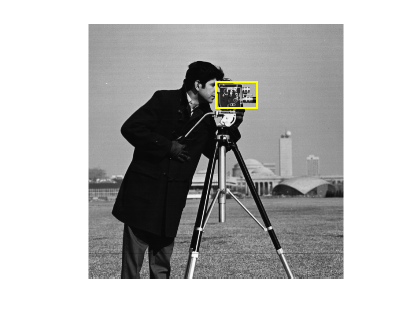


% step 3 -  use function size() to get the size of template image
M_t = size(t, 1);
N_t = size(t, 2);

% step 4 - use insertShape() to display the matched box
yoffSet = y_n - M_t;
xoffSet = x_n - N_t;
I_res1 = insertShape(I, "rectangle", [xoffSet, yoffSet, N_t, M_t], LineWidth = 2);
imshow(I_res1)


% for each experiment, display the related search image, template image,
% and matched box




Experiment 2 Contrast Change of template vs original image

D_two = xcorr2(I, t_ill)

D_two =        28392       57174       86239      114456      143213      171440      199603      229274      258505      288058      317103      346681      377653      397939      403940      408884      414426      415264      416447      420375      425282      429200      434013      439334      444712      449918      454224      459745      464762      470209      479847      487602      492080      496324      501716      506818      507421      508276      529223      561830      593980      594263      595142      595847      597315      597856      599505      600092      600704      601361
       57824      114792      172605      230176      288461      345956      403627      463229      522725      582497      640567      699774      761329      812549      836468      848434      860636      866687      882884      899160      917265      934720      952282      970428      989359     1008628     1026451     1045086     1062378     1082989     1106600     1125417     11

N_D_two = normxcorr2(t_ill, I)

N_D_two =     0.0275    0.0387    0.0479    0.0553    0.0618    0.0676    0.0723    0.0782    0.0836    0.0887    0.0932    0.0977    0.1029    0.1006    0.0890    0.0778    0.0672    0.0547    0.0430    0.0337    0.0251    0.0167    0.0089    0.0017   -0.0049   -0.0116   -0.0183   -0.0243   -0.0304   -0.0360   -0.0394   -0.0438   -0.0495   -0.0551   -0.0601   -0.0651   -0.0718   -0.0783   -0.0764   -0.0699   -0.0637   -0.0639   -0.0639   -0.0639   -0.0638   -0.0639   -0.0637   -0.0638   -0.0640   -0.0640
    0.0395    0.0555    0.0684    0.0794    0.0893    0.0977    0.1053    0.1138    0.1218    0.1292    0.1358    0.1425    0.1497    0.1517    0.1406    0.1253    0.1102    0.0940    0.0828    0.0726    0.0632    0.0542    0.0455    0.0374    0.0303    0.0233    0.0160    0.0093    0.0022   -0.0034   -0.0080   -0.0139   -0.0201   -0.0258   -0.0312   -0.0361   -0.0400   -0.0500   -0.0528   -0.0446   -0.0359   -0.0360   -0.0360   -0.0362   -0.0363   -0.0361   -0.0359   -0.0359   -0.036


% step 2 - find the peak value location in the correlation matrix

[x_two,y_two] = find(D_two == max(abs(D_two(:))))

x_two = 29

y_two = 139

[y_n_two, x_n_two] = find(N_D_two == max(abs(N_D_two(:))))

y_n_two = 85

x_n_two = 170


% step 3 -  use function size() to get the size of template image
M_till = size(t_ill, 1);
N_till = size(t_ill, 2);

% step 4 - use insertShape() to display the matched box
yoffTwo = y_n_two - M_till;
xoffTwo = x_n_two - N_till;
I_res2 = insertShape(I, "rectangle", [xoffTwo, yoffTwo, N_till, M_till], LineWidth = 2);
imshow(I_res2)

Experiment 5 Contrat Change of only image.

D_5 = xcorr2(I_ill, t)

D_5 =        31706       63885       96467      128016      160222      191725      223338      256472      289120      322106      354669      387634      422055      445485      454322      462177      470591      474300      478411      485090      493054      499658      507425      515574      523938      532007      539355      547997      556105      564564      577294      588175      595653      602935      611284      619344      622943      626741      651209      687536      723312      723828      724953      725756      727562      728375      730425      731313      732176      732899
       64624      128371      193205      257499      322718      386994      451551      518119      584447      651128      716036      782033      850445      908233      938168      955982      974048      985841     1008124     1030099     1054438     1077666     1101326     1125502     1150559     1175824     1199990     1224829     1248450     1275245     1305207     1330349     1353

N_D_5 = normxcorr2(t, I_ill)

N_D_5 =     0.0275    0.0385    0.0479    0.0553    0.0618    0.0674    0.0721    0.0781    0.0834    0.0885    0.0930    0.0975    0.1027    0.1002    0.0887    0.0775    0.0670    0.0545    0.0429    0.0336    0.0250    0.0166    0.0087    0.0015   -0.0051   -0.0117   -0.0184   -0.0243   -0.0304   -0.0359   -0.0393   -0.0437   -0.0493   -0.0549   -0.0599   -0.0649   -0.0716   -0.0780   -0.0762   -0.0697   -0.0635   -0.0637   -0.0637   -0.0638   -0.0636   -0.0637   -0.0636   -0.0636   -0.0638   -0.0639
    0.0395    0.0555    0.0684    0.0793    0.0892    0.0976    0.1052    0.1137    0.1216    0.1289    0.1355    0.1422    0.1494    0.1513    0.1402    0.1250    0.1099    0.0937    0.0825    0.0723    0.0629    0.0539    0.0452    0.0372    0.0300    0.0230    0.0159    0.0092    0.0022   -0.0034   -0.0080   -0.0139   -0.0201   -0.0258   -0.0311   -0.0361   -0.0399   -0.0499   -0.0527   -0.0445   -0.0358   -0.0360   -0.0360   -0.0362   -0.0362   -0.0360   -0.0359   -0.0359   -0.0360 


% step 2 - find the peak value location in the correlation matrix

[x_5,y_5] = find(D_5 == max(abs(D_5(:))))

x_5 = 29

y_5 = 139

[y_n_5, x_n_5] = find(N_D_5 == max(abs(N_D_5(:))))

y_n_5 = 85

x_n_5 = 170

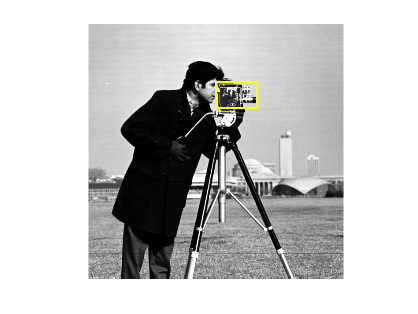


% step 3 -  use function size() to get the size of template image
M_5 = size(t, 1);
N_5 = size(t, 2);

% step 4 - use insertShape() to display the matched box
yoff5 = y_n_5 - M_5;
xoff5 = x_n_5 - N_5;
I_res5 = insertShape(I_ill, "rectangle", [xoff5, yoff5, N_5, M_5], LineWidth = 2);
imshow(I_res5)

Experiment 3 Contrast change of template and Image

D_3 = xcorr2(I_ill, t_ill)

D_3 =        34762       70061      105747      140336      175646      210205      244747      281172      317104      353392      389054      425332      463268      488128      495476      501570      508373      509502      511011      515805      521970      526679      532657      539158      545823      552226      557636      564614      570890      577625      589492      599066      604662      609973      616597      622934      623792      624869      650693      690731      730196      730644      731749      732546      734438      735215      737361      738232      739024      739704
       70816      140707      211733      282362      353968      424423      495194      568368      641459      714767      786014      858570      934016      996848     1026146     1040935     1055959     1063429     1083367     1103312     1125734     1147088     1168809     1191058     1214365     1238099     1260257     1283339     1304882     1330238     1359332     1382611     1403

N_D_3 = normxcorr2(t_ill, I_ill)

N_D_3 =     0.0275    0.0387    0.0479    0.0553    0.0618    0.0676    0.0723    0.0782    0.0836    0.0887    0.0932    0.0977    0.1029    0.1006    0.0890    0.0778    0.0672    0.0547    0.0431    0.0338    0.0252    0.0168    0.0089    0.0018   -0.0049   -0.0115   -0.0182   -0.0242   -0.0303   -0.0358   -0.0393   -0.0436   -0.0493   -0.0549   -0.0599   -0.0649   -0.0716   -0.0781   -0.0762   -0.0697   -0.0635   -0.0637   -0.0638   -0.0638   -0.0636   -0.0637   -0.0636   -0.0636   -0.0638   -0.0639
    0.0395    0.0555    0.0684    0.0794    0.0893    0.0977    0.1053    0.1138    0.1218    0.1292    0.1358    0.1425    0.1497    0.1517    0.1406    0.1253    0.1102    0.0940    0.0828    0.0726    0.0632    0.0542    0.0455    0.0374    0.0303    0.0233    0.0161    0.0094    0.0024   -0.0032   -0.0078   -0.0137   -0.0199   -0.0256   -0.0310   -0.0359   -0.0398   -0.0497   -0.0526   -0.0444   -0.0356   -0.0358   -0.0358   -0.0360   -0.0361   -0.0359   -0.0357   -0.0358   -0.0358 


% step 2 - find the peak value location in the correlation matrix

[x_3,y_3] = find(D_3 == max(abs(D_3(:))))

x_3 = 29

y_3 = 139

[y_n_3, x_n_3] = find(N_D_3 == max(abs(N_D_3(:))))

y_n_3 = 85

x_n_3 = 170

% step 3 -  use function size() to get the size of template image
M_3 = size(t_ill, 1);
N_3 = size(t_ill, 2);

% step 4 - use insertShape() to display the matched box
yoff3 = y_n_3 - M_3;
xoff3 = x_n_3 - N_3;
I_res3 = insertShape(I, "rectangle", [xoff3, yoff3, N_3, M_3], LineWidth = 2);
I_test = insertShape(I_ill, "rectangle", [xoff3, yoff3, N_3, M_3], LineWidth = 2);
imshow(I_res3)

imshow(I_test)

Experiment 4 Compare rotated template to Image

D_4 = xcorr2(I, t_rot)

D_4 =        28080       58104       87351      116037      145396      174125      203669      233385      262913      292756      322154      351869      381935      412495      443819      460765      467537      496502      528118      560770      594635      628233      658847      682356      699134      721675      722629      723504      724610      725841      726517      728087      728768      730050      731676      732844      733637      735095      735887      737244      738096      739075      740463      740876      741750      743519      744383      745322      746337      746892
       57348      114981      165869      207584      246122      284725      324916      364882      404723      444106      481511      518807      556531      594474      633148      654402      672738      734144      798329      863391      930221      987725     1026408     1055438     1079231     1109696     1111284     1113045     1114795     1116571     1119004     1120544     1121

N_D_4 = normxcorr2(t_rot, I)

N_D_4 =     0.0342    0.0515    0.0633    0.0732    0.0821    0.0898    0.0972    0.1045    0.1113    0.1179    0.1237    0.1294    0.1350    0.1408    0.1470    0.1422    0.1295    0.1340    0.1402    0.1471    0.1541    0.1611    0.1654    0.1654    0.1616    0.1613    0.1613    0.1613    0.1613    0.1613    0.1614    0.1614    0.1612    0.1613    0.1613    0.1613    0.1612    0.1613    0.1611    0.1613    0.1613    0.1613    0.1614    0.1611    0.1611    0.1615    0.1614    0.1611    0.1613    0.1613
    0.0494    0.0713    0.0789    0.0768    0.0727    0.0702    0.0696    0.0694    0.0694    0.0691    0.0681    0.0672    0.0663    0.0658    0.0657    0.0565    0.0454    0.0578    0.0709    0.0840    0.0969    0.1052    0.1043    0.0991    0.0923    0.0884    0.0886    0.0885    0.0884    0.0884    0.0886    0.0884    0.0882    0.0888    0.0889    0.0889    0.0886    0.0889    0.0888    0.0889    0.0890    0.0886    0.0887    0.0888    0.0887    0.0885    0.0886    0.0889    0.0892 


% step 2 - find the peak value location in the correlation matrix

[x_4,y_4] = find(D_4 == max(abs(D_4(:))))

x_4 = 41

y_4 = 148

[y_n_4, x_n_4] = find(N_D_4 == max(abs(N_D_4(:))))

y_n_4 = 92

x_n_4 = 91

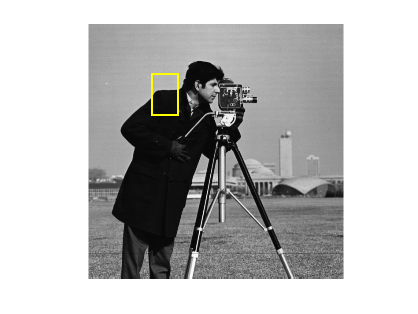


% step 3 -  use function size() to get the size of template image
M_4 = size(t_rot, 1);
N_4 = size(t_rot, 2);

% step 4 - use insertShape() to display the matched box
yoff4 = y_n_4 - M_4;
xoff4 = x_n_4 - N_4;
I_res4 = insertShape(I, "rectangle", [xoff4, yoff4, N_4, M_4], LineWidth = 2);
imshow(I_res4)

## Problem 2 - binary image matching

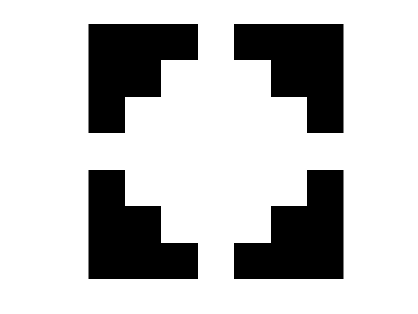

BW  = zeros(100);
b = strel( 'diamond',3);
b = b.Neighborhood;
R = b;

x = [3, 3, 50, 78, 90 ];
y = [5, 60, 20, 80, 1 ];
for i = 1 : length( x )
    BW(y(i):y(i)+6,x(i):x(i)+6) = b;
end

b = strel( 'square',5);
b = b.Neighborhood;

x = [31, 35, 80, 7, 60, 15, 20, 70 ];
y = [5, 60, 60, 80, 30, 20, 50, 66 ];
for i = 1 : length( x )
    BW(y(i):y(i)+4,x(i):x(i)+4) = b;
end

imshow(R)

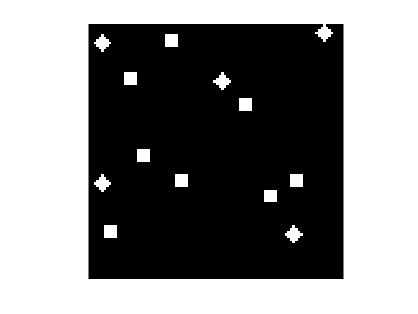

imshow(BW)


% now, BW is your search image, R is your reference image

% write your code here

% use cross correlation from problem 1 to find matching, record time

tic;
D_b = xcorr2(BW, R);
N_D_b = normxcorr2(R, BW)

N_D_b =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 


% step 2 - find the peak value location in the correlation matrix

[x_b,y_b] = find(D_b == max(abs(D_b(:))));
[y_n_b, x_n_b] = find(N_D_b == max(abs(N_D_b(:))));
toc;

Elapsed time is 0.022723 seconds.


fprintf('Time taken for Cross Correlation method: %f seconds\n', toc);

Time taken for Cross Correlation method: 0.028659 seconds


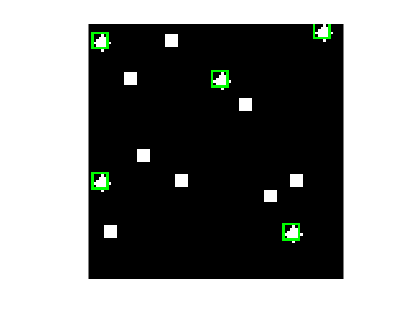

% step 3 -  use function size() to get the size of template image
M_b = size(R, 1);
N_b = size(R, 2);

% step 4 - use insertShape() to display the matched box
yoffb = y_n_b - M_b;
xoffb = x_n_b - N_b;
I_resb = BW;
for i = 1:size(xoffb)
    I_resb = insertShape(I_resb, "rectangle", [xoffb(i), yoffb(i), N_b, M_b], Color="Green", LineWidth = 1);    
end
imshow(I_resb)

tic;
% use chamferMatch() to get the distance transform image Q
Q = chamferMatch(BW, R);
% then find the minimum distance in Q, record time
[y_n_c, x_n_c] = find(Q == min(Q(:)));
toc;

Elapsed time is 0.031670 seconds.


fprintf('Time taken for min distnace and chamfer Match is: %f seconds\n', toc);

Time taken for min distnace and chamfer Match is: 0.036461 seconds


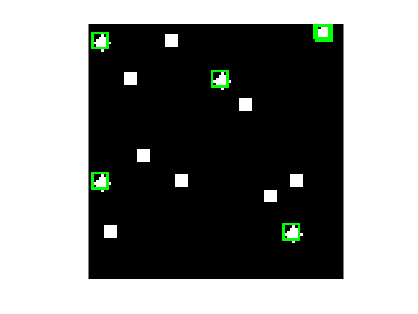

for i = 1:size(x_n_c)
    I_resc = insertShape(I_resb, "rectangle", [x_n_c(i), y_n_c(i), N_b, M_b], Color="Green", LineWidth = 1);    
end
imshow(I_resc)


% display all the matching using insertShape()

% an example of recording time
% t1 = cputime
% run your code
% time_spent = cputime - t1